## Formulation

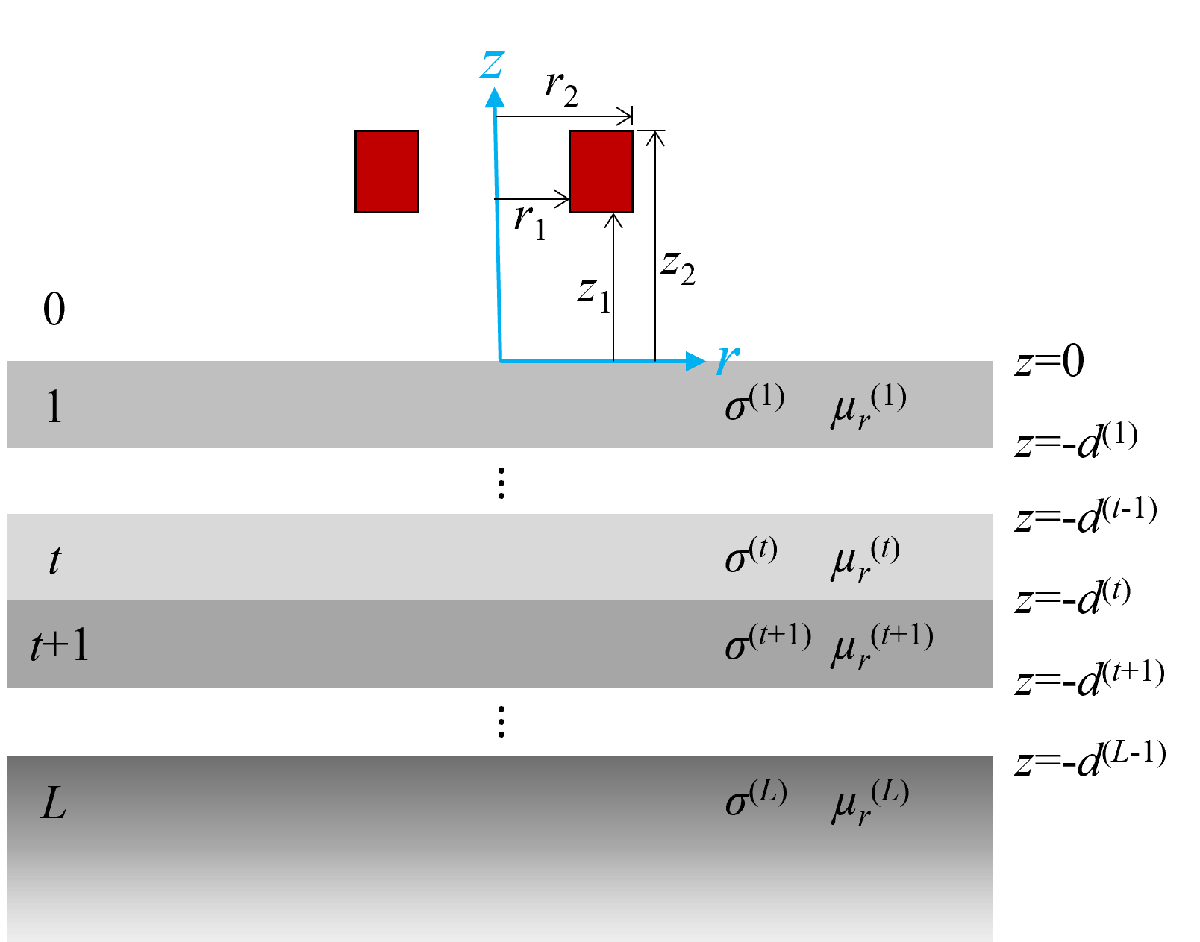

The governing equation for the eddy current problem is 


$$\frac{\partial^2 A_{\theta } }{\partial r^2 }+\frac{1}{r}\frac{\partial A_{\theta } }{\partial r}-\frac{A_{\theta } }{r^2 }+\frac{\partial^2 A_{\theta } }{\partial z^2 }=k^2 A_{\theta } \;\;\;\textrm{where}\;\;\;k^2 =j\omega \mu_0 \mu_r \sigma$$


The magnetic vector potential in air region above the plate thus have the form


$$A_{\theta }^{\left(0\right)} \left(r,z\right)=\int_0^{\infty } J_1 \left(\kappa r\right)\left\lbrack C^{\left(s\right)} e^{\kappa z} +D^{\left(\textrm{ec}\right)} e^{-\kappa z} \right\rbrack d\kappa =\sum_{i=1}^{\infty } J_1 \left(\kappa_i r\right)\left\lbrack C_i^{\left(s\right)} e^{\kappa_i z} +D_i^{\left(\textrm{ec}\right)} e^{-\kappa_i z} \right\rbrack \frac{2}{{\kappa_i \left({\textrm{hJ}}_0 \left(\kappa_i h\right)\right)}^2 }$$


The series solution is obtained by the truncated region eigen-function expansion (TREE) method. Which truncates the solution region at $r=h$, and $\kappa_i$ are the positive roots of $J_1 \left(\kappa_i h\right)=0$.

In particular, the $C^{\left(s\right)} e^{\kappa z}$ term is due to the coil source, and the $D^{\left(\textrm{ec}\right)} e^{-\kappa z}$ term is due to eddy current.

The magnetic vector potential in each layer *t*=1~*L* have the form


$$A_{\theta }^{\left(t\right)} \left(r,z\right)=\int_0^{\infty } J_1 \left(\kappa r\right)\left\lbrack C^{\left(t\right)} e^{\lambda^{\left(t\right)} z} +D^{\left(t\right)} e^{-\lambda^{\left(t\right)} z} \right\rbrack d\kappa =\sum_{i=1}^{\infty } J_1 \left(\kappa_i r\right)\left\lbrack C_i^{\left(t\right)} e^{\lambda_i^{\left(t\right)} z} +D_i^{\left(t\right)} e^{-\lambda_i^{\left(t\right)} z} \right\rbrack \frac{2}{{\kappa_i \left({\textrm{hJ}}_0 \left(\kappa_i h\right)\right)}^2 }\;\;\;\textrm{where}\;\;\;{\lambda_i^{\left(t\right)} }^2 ={\kappa_i }^2 +{k^{\left(t\right)} }^2$$


Additionally, $D^{\left(L\right)} =0$ since layer *L* extends to $z=-\infty$.

The magnetic flux density can then be derived from


$$B_r =-\frac{\partial A_{\theta } }{\partial z}$$
     
$$B_z =\frac{1}{r}\frac{\partial \left({\textrm{rA}}_{\theta } \right)}{\partial r}$$


### Source term

#### Filamentary coil

For a filamentary coil at $z=z_0$ and radius $r_0$, the coefficient $C^{\left(s\right)}$ is given by


$$C^{\left(s\right)} =\frac{\mu_0 I}{2}r_0 J_1 \left(\kappa r_0 \right)e^{-\kappa z_0 }$$


If the $z$ coordinate of evaluation point is not below the coil, the $C^{\left(s\right)} e^{\kappa z}$ term must be replaced by


$$\frac{\mu_0 I}{2}r_0 J_1 \left(\kappa r_0 \right)\times \left\lbrace \begin{array}{ll}
e^{\kappa \left(z-z_0 \right)}  & z<z_0 \\
e^{\kappa \left(z_0 -z\right)}  & z>z_0 
\end{array}\right.$$


#### Cylindrical coil

For a cylindrical coil from $z=z_1$ to $z=z_2$ and has inner radius $r_1$, outer radius $r_2$. The coefficient $C^{\left(s\right)}$ is given by


$$C^{\left(s\right)} =\frac{\mu_0 i_0 }{2}\frac{\chi \left(\kappa r_1 ,\kappa r_2 \right)}{\kappa^3 }\left(e^{-\kappa z_1 } -e^{-\kappa z_2 } \right)\;\;\;\textrm{where}\;\;\;\chi \left(x_1 ,x_2 \right)=\int_{x_1 }^{x_2 } {\textrm{xJ}}_1 \left(x\right)\textrm{dx}\;\;\;\textrm{and}\;\;\;i_0 =\frac{\textrm{NI}}{\left(r_2 -r_1 \right)\left(z_2 -z_1 \right)}$$


If the $z$ coordinate of evaluation point is not below the coil, the $C^{\left(s\right)} e^{\kappa z}$ term must be replaced by


$$\frac{\mu_0 i_0 }{2}\frac{\chi \left(\kappa r_1 ,\kappa r_2 \right)}{\kappa^3 }\times$$

$$\begin{cases} 
    e^{\kappa (z - z_1)} - e^{\kappa (z - z_2)}      &           z < z_1 \\
    2 - e^{\kappa (z - z_2)} - e^{\kappa (z_1 - z)} & z_1 < z < z_2 \\
    e^{\kappa (z_2 - z)} - e^{\kappa (z_1 - z)}      & z_2 < z           \\
\end{cases} $$


### Computation of coefficients

The interface conditions between layer *t* and layer *t*+1 are


$${\left\lbrack \begin{array}{c}
A_{\theta }^{\left(t\right)} =A_{\theta }^{\left(t+1\right)} \\
\frac{1}{\mu_r^{\left(t\right)} }\frac{\partial A_{\theta }^{\left(t\right)} }{\partial z}=\frac{1}{\mu_r^{\left(t+1\right)} }\frac{\partial A_{\theta }^{\left(t+1\right)} }{\partial z}
\end{array}\right\rbrack }_{z=-d^{\left(t\right)} }$$


Which leads to the following matrix equation


$$\left\lbrack \begin{array}{c}
C^{\left(t\right)} \\
D^{\left(t\right)} 
\end{array}\right\rbrack =\frac{1}{2}\left\lbrack \begin{array}{cc}
e^{\left(-\lambda^{\left(t+1\right)} +\lambda^{\left(t\right)} \right)d^{\left(t\right)} } \left(1+\frac{\mu_r^{\left(t\right)} }{\mu_r^{\left(t+1\right)} }\frac{\lambda^{\left(t+1\right)} }{\lambda^{\left(t\right)} }\right) & e^{\left(\lambda^{\left(t+1\right)} +\lambda^{\left(t\right)} \right)d^{\left(t\right)} } \left(1-\frac{\mu_r^{\left(t\right)} }{\mu_r^{\left(t+1\right)} }\frac{\lambda^{\left(t+1\right)} }{\lambda^{\left(t\right)} }\right)\\
e^{\left(-\lambda^{\left(t+1\right)} -\lambda^{\left(t\right)} \right)d^{\left(t\right)} } \left(1-\frac{\mu_r^{\left(t\right)} }{\mu_r^{\left(t+1\right)} }\frac{\lambda^{\left(t+1\right)} }{\lambda^{\left(t\right)} }\right) & e^{\left(\lambda^{\left(t+1\right)} -\lambda^{\left(t\right)} \right)d^{\left(t\right)} } \left(1+\frac{\mu_r^{\left(t\right)} }{\mu_r^{\left(t+1\right)} }\frac{\lambda^{\left(t+1\right)} }{\lambda^{\left(t\right)} }\right)
\end{array}\right\rbrack \left\lbrack \begin{array}{c}
C^{\left(t+1\right)} \\
D^{\left(t+1\right)} 
\end{array}\right\rbrack$$


Starting from layer *L*-1 and going up iteratively, the coefficient of any layer can be related to the coefficient of layer *L*.


$$\left\lbrack \begin{array}{c}
C^{\left(t\right)} \\
D^{\left(t\right)} 
\end{array}\right\rbrack ={\mathbf{V}}^{\left(t\right)} \left\lbrack \begin{array}{c}
C^{\left(L\right)} \\
0
\end{array}\right\rbrack$$


And by applying the interface conditions between layer 1 and the air region, we obtain


$$C^{\left(L\right)} =\frac{2\kappa \mu_r^{\left(1\right)} }{\left(\kappa \mu_r^{\left(1\right)} +\lambda^{\left(1\right)} \right)V_{11}^{\left(1\right)} +\left(\kappa \mu_r^{\left(1\right)} -\lambda^{\left(1\right)} \right)V_{21}^{\left(1\right)} }C^{\left(s\right)}$$



$$D^{\left(\textrm{ec}\right)} =\frac{\left(\kappa \mu_r^{\left(1\right)} -\lambda^{\left(1\right)} \right)V_{11}^{\left(1\right)} +\left(\kappa \mu_r^{\left(1\right)} +\lambda^{\left(1\right)} \right)V_{21}^{\left(1\right)} }{\left(\kappa \mu_r^{\left(1\right)} +\lambda^{\left(1\right)} \right)V_{11}^{\left(1\right)} +\left(\kappa \mu_r^{\left(1\right)} -\lambda^{\left(1\right)} \right)V_{21}^{\left(1\right)} }C^{\left(s\right)}$$


## Function

### Usage

Initiate a coil above plate in axisymmetric coordinates model.

Evaluate field at position `r`, `z. fieldname` could be `'Atheta'` `'Etheta'` `'Jtheta'` `'Br'` `'Bz'` `'Hr'` `'Hz'`

### Coils

If there is a single coil, `coils` is a *structure array.* If there are more than one coil, `coils` is a *cell array.*

Coil could be of type filamentary or cylindrical.

### Layers

`layers` is a *cell array*

Specify the electrical conductivity, relative magnetic permeability, and thickness of each layer. The last layer must have infinite thicknes.

function Model = CoilAbovePlate2D(coils, layers, varargin)

if ~iscell(coils)
    coils = {coils};
end
r_base = 0;
for p = 1:numel(coils)
    switch lower(coils{p}.type)
        case 'filamentary'
            r = coils{p}.r0;
        case 'cylindrical'
            r = coils{p}.r2;
        otherwise
            error('Unknown coil type "%s"', coils{p}.type)
    end
    if r > r_base; r_base = r; end
end

for t = 1:numel(layers)
    assert(layers{t}.sigma >= 0);
    assert(layers{t}.mur >= 1);
    assert(layers{t}.thickness > 0);
end
assert(layers{end}.thickness == Inf)

p = inputParser;
addParameter(p, 'TruncateRadius', r_base * 10);
addParameter(p, 'SummationTerms', 50);
parse(p, varargin{:});

h = p.Results.TruncateRadius;
terms = p.Results.SummationTerms;
kappa = besselzero(1, terms) / h;
tree_coef = 2 ./ kappa ./ (h * besselj(0,kappa*h)).^2;

Model.coils = coils;
Model.layers = layers;
Model.impl = struct('kappa',kappa, 'tree_coef',tree_coef);

Model.EvaluateField = @(fieldnames, r,z,omega) EvaluateField(Model, fieldnames, r, z, omega);

end

function varargout = EvaluateField(Model, fieldnames, r, z, omega)

if ~iscell(fieldnames)
    fieldnames = {fieldnames};
end
varargout = cell(1, numel(fieldnames));

kappa = Model.impl.kappa;
Cs  = gamma_s(Model.coils, kappa, 0);
[Dec, Ct, Dt] = CoilAbovePlateCoefficients(Model.layers, kappa, omega, Cs);

for p = 1:numel(fieldnames)
    varargout{p} = zeros(size(r));
    for z_layer = reshape(unique(z), 1,[])
        mask = z == z_layer;
        varargout{p}(mask) = EvaluateField_single_z(Model, fieldnames{p}, Dec, Ct, Dt, r(mask), z_layer, omega);
    end
end

end

function field = EvaluateField_single_z(Model, fieldname, Dec, Ct, Dt, r, z, omega)

assert(isscalar(z))
mu0 = 4*pi * 1e-7;

kappa     = Model.impl.kappa;
tree_coef = Model.impl.tree_coef;

diff_z = false;
if strcmp(fieldname, 'Br') || strcmp(fieldname, 'Hr')
    diff_z = true;
end

idx = FindLayer(Model.layers, z);
if idx == 0
    sigma = 0;
    mur = 1;

    if ~diff_z
        alpha    = gamma_s(Model.coils, kappa, z)         + Dec .* exp(-kappa*z);
    else
        dalphadz = gamma_s(Model.coils, kappa, z, 'diff') - Dec .* kappa .* exp(-kappa*z);
    end
else
    sigma = Model.layers{idx}.sigma;
    mur   = Model.layers{idx}.mur;

    Ct = Ct(:,:,idx);
    Dt = Dt(:,:,idx);
    lambda = sqrt(kappa.^2 + 1j * omega * mu0 * mur * sigma);
    if ~diff_z
        alpha    =  Ct .* exp(lambda*z) + Dt .* exp(-lambda*z);
    else
        dalphadz = (Ct .* exp(lambda*z) - Dt .* exp(-lambda*z)) .* lambda;
    end
end

sz = [ones(1,ndims(r)) length(kappa)];
kappa      = reshape(kappa,     sz);
tree_coef  = reshape(tree_coef, sz);
alpha      = reshape(alpha,     sz);

if strcmp(fieldname, 'Atheta') || strcmp(fieldname, 'Etheta') || strcmp(fieldname, 'Jtheta')
    integrand = besselj(1,kappa.*r) .* alpha;    
    if strcmp(fieldname, 'Etheta');     integrand = integrand * (-1j * omega);
    elseif strcmp(fieldname, 'Jtheta'); integrand = integrand * (-1j * omega * sigma);
    end
elseif strcmp(fieldname, 'Br') || strcmp(fieldname, 'Hr')
    integrand = -besselj(1,kappa.*r) .* dalphadz;
    if strcmp(fieldname, 'Hr');         integrand = integrand / (mu0*mur);
    end
elseif strcmp(fieldname, 'Bz') || strcmp(fieldname, 'Hz')
    integrand = besselj(0,kappa.*r) .* alpha .* kappa;
    if strcmp(fieldname, 'Hz');         integrand = integrand / (mu0*mur);
    end
else
    error('Unknown field name "%s"', fieldname)
end
field = sum(tree_coef .* integrand, length(sz));

end

function val = gamma_s(coils, kappa, z, varargin)

is_diff = ~isempty(varargin);
mu0 = 4*pi * 1e-7;

val = 0;
for p = 1:numel(coils)
    coil = coils{p};
    switch lower(coil.type)
        case 'filamentary'
            if ~is_diff
                if z < coil.z0; temp = exp(kappa * (z - coil.z0));
                else;           temp = exp(kappa * (coil.z0 - z));
                end
            else
                if z < coil.z0; temp =  kappa .* exp(kappa * (z - coil.z0));
                else;           temp = -kappa .* exp(kappa * (coil.z0 - z));
                end
            end
            val = val + mu0*coil.I/2 * coil.r0 * besselj(1,kappa*coil.r0) .* temp;

        case 'cylindrical'
            i0 = coil.N * coil.I / (coil.r2 - coil.r1) / (coil.z2 - coil.z1);
            if ~is_diff
                if z < coil.z1;      temp =     exp(kappa * (z - coil.z1)) - exp(kappa * (z - coil.z2));
                elseif z <= coil.z2; temp = 2 - exp(kappa * (z - coil.z2)) - exp(kappa * (coil.z1 - z));
                else;                temp =     exp(kappa * (coil.z2 - z)) - exp(kappa * (coil.z1 - z));
                end
            else
                if z < coil.z1;      temp =  kappa .* (  exp(kappa * (z - z1)) - exp(kappa * (z - z2)) );
                elseif z <= coil.z2; temp =  kappa .* ( -exp(kappa * (z - z2)) + exp(kappa * (z1 - z)) );
                else;                temp = -kappa .* (  exp(kappa * (z2 - z)) - exp(kappa * (z1 - z)) );
                end
            end
            val = val + mu0*i0/2 ./ kappa.^3 .* chi(kappa*coil.r1, kappa*coil.r2) .* temp;

        otherwise
            error('Unknown coil type "%s"', coils{p}.type)
    end
end

end

function val = chi(x1,x2)
val = zeros(size(x1));
for i = 1:numel(x1)
    val(i) = integral(@(x)x.*besselj(1,x), x1(i),x2(i));
end
end

function idx = FindLayer(layers, z)
if z > 0
    idx = 0;
    return
end
bottom_z = 0;
for idx = 1:numel(layers)
    bottom_z = bottom_z - layers{idx}.thickness;
    if z >= bottom_z
        return
    end
end
end